Values of SFD and BMD

BMDmax = 78.0978

SFDmax = 304.1668

first_axle_position_for_BMDmax = 110

first_axle_position_for_SFDmax = 344

x_centroid = 50.0000

y_centroid = 89.4665

I_yy = 8.9007e+05

Qcent = 1.0165e+04

Qglue = 7.4329e+03

FOS_tens = 3.8216

FOS_comp = 2.2395

FOS_shear = 2.9247

FOS_glue = 39.3688

FOS_buck1 = 5.3255

FOS_buck2 = 31.0097

FOS_buck3 = 13.2777

FOS_buckV = 2.9926

minFOS = 2.2395

Pf = 1.0123e+03

Mf_buck1 = 415.9122

Mf_buck2 = 2.4218e+03

Mf_buck3 = 1.0370e+03

maxBMD_location = 626

csA_total = 615.8484

Volume_total = 7.7597e+05

max_shear_force_allowable = 296.5320

bf_Shearsupport_dist = 20

max_BM_allowable = 58.3012


run('Bridge_MainDesign.m');

% Individual Design Parameters
main_tfb = tfb(1);
main_tfh = tfh(1);
main_gch = lgch(1);
main_gcb = lgcb(1);
main_wh = lwh(1);
main_wb = lwb(1);
main_bfb = bfb(1);
main_bfh = bfh(1);
main_Q = Qcent;
main_I = I_yy;

Main_design_csA = csA_total;
onesL = ones(1, length(SFD_envelope))

onesL =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


BMDmax = 78.0978

SFDmax = 304.1668

first_axle_position_for_BMDmax = 110

first_axle_position_for_SFDmax = 344

x_centroid = 50.0000

y_centroid = 77.2312

I_yy = 1.5594e+06

Qcent = 1.5110e+04

Qglue = 1.0541e+04

S_top = 2.1419

S_bot = 3.8678

shear_cent = 1.1603

shear_glue = 0.0411

FOS_tens = 7.7564

FOS_comp = 2.8013

FOS_shear = 3.4473

FOS_glue = 48.6392

FOS_buck1 = 6.6613

FOS_buck2 = 38.7874

FOS_buck3 = 8.4648

FOS_buckV = 3.5653

minFOS = 2.8013

Pf = 1.2662e+03

Mf_buck1 = 520.2293

Mf_buck2 = 3.0292e+03

Mf_buck3 = 661.0780

maxBMD_location = 626

csA_total = 714.2226

Volume_total = 8.9992e+05

V_support_span1 = bf_Shearsupport_dist - 1;
V_support_span2 = length(SFD_envelope) - bf_Shearsupport_dist;
BM_support_start = dist_from_ends_for_BMSupport;
BM_support_end = length(BMD_envelope) - dist_from_ends_for_BMSupport - 1;

Vf_shear_final = Vf_shear * ones(1, L + 1);
Vf_glue_final = Vf_glue * ones(1, L + 1);
Vf_buckV_final = Vf_buckV * ones(1, L + 1);

Mf_tens_final = Mf_tens * ones(1, L + 1);
Mf_comp_final = Mf_comp * ones(1, L + 1);
Mf_buck1_final = Mf_buck1 * ones(1, L + 1);
Mf_buck2_final = Mf_buck2 * ones(1, L + 1);
Mf_buck3_final = Mf_buck3 * ones(1, L + 1);

run('Bridge_ShearSupport.m');

BMDmax = 78.0978

SFDmax = 304.1668

first_axle_position_for_BMDmax = 110

first_axle_position_for_SFDmax = 344

x_centroid = 50

y_centroid = 93.9359

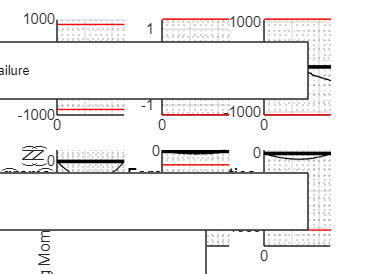

I_yy = 9.6365e+05

Qcent = 1.1206e+04

Qglue = 9.2046e+03

FOS_tens = 3.9407

FOS_comp = 2.8404

FOS_shear = 2.8723

FOS_glue = 34.4191

FOS_buck1 = 15.1975

FOS_buck2 = 88.4925

FOS_buck3 = 23.1108

FOS_buckV = 2.9706

minFOS = 2.8404

Pf = 1.2839e+03

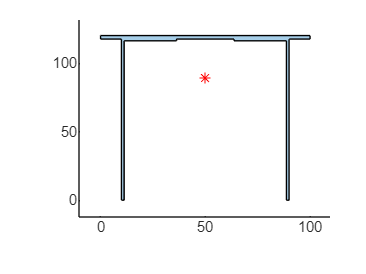

maxBMD_location = 626

csA_total = 739.6226

Volume_total = 9.3192e+05

max_shear_force_allowable = 291.2212

bf_Shearsupport_dist = 34

max_BM_allowable = 73.9441

% Individual Design Parameters
shearsupp_tfb = tfb(1);
shearsupp_tfh = tfh(1);
shearsupp_gch = lgch(1);
shearsupp_gcb = lgcb(1);
shearsupp_wh = lwh(1);
shearsupp_wb = lwb(1);
shearsupp_bfb = bfb(1);
shearsupp_bfh = bfh(1);
shearsupp_Q = Qcent;
shearsupp_I = I_yy;

Shear_support_csA = csA_total;
Vf_shear_final(1:V_support_span1) = Vf_shear * onesL(1, V_support_span1);
Vf_glue_final(1:V_support_span1) = Vf_glue * onesL(1, V_support_span1);
Vf_buckV_final(1:V_support_span1) = Vf_buckV * onesL(1, V_support_span1);
Mf_tens_final(1:V_support_span1) = Mf_tens * onesL(1, V_support_span1);
Mf_comp_final(1:V_support_span1) = Mf_comp * onesL(1, V_support_span1);
Mf_buck1_final(1:V_support_span1) = Mf_buck1 * onesL(1, V_support_span1);
Mf_buck2_final(1:V_support_span1) = Mf_buck2 * onesL(1, V_support_span1);
Mf_buck3_final(1:V_support_span1) = Mf_buck3 * onesL(1, V_support_span1);

Vf_shear_final(V_support_span2:end) = Vf_shear * onesL(V_support_span2:end);
Vf_glue_final(V_support_span2:end) = Vf_glue * onesL(V_support_span2:end);
Vf_buckV_final(V_support_span2:end) = Vf_buckV * onesL(V_support_span2:end);
Mf_tens_final(V_support_span2:end) = Mf_tens * onesL(V_support_span2:end);
Mf_comp_final(V_support_span2:end) = Mf_comp * onesL(V_support_span2:end);
Mf_buck1_final(V_support_span2:end) = Mf_buck1 * onesL(V_support_span2:end);
Mf_buck2_final(V_support_span2:end) = Mf_buck2 * onesL(V_support_span2:end);
Mf_buck3_final(V_support_span2:end) = Mf_buck3 * onesL(V_support_span2:end);

run('Bridge_BMSupport.m');

BM_tfb = tfb(1);
BM_tfh = tfh(1);
BM_gch = lgch(1);
BM_gcb = lgcb(1);
BM_wh = lwh(1);
BM_wb = lwb(1);
BM_bfb = bfb(1);
BM_bfh = bfh(1);
BM_Q = Qcent;
BM_I = I_yy;

BM_support_csA = csA_total;
Vf_shear_final(BM_support_start:BM_support_end) = Vf_shear * onesL(BM_support_start:BM_support_end);
Vf_glue_final(BM_support_start:BM_support_end) = Vf_glue * onesL(BM_support_start:BM_support_end);
Vf_buckV_final(BM_support_start:BM_support_end) = Vf_buckV * onesL(BM_support_start:BM_support_end);
Mf_tens_final(BM_support_start:BM_support_end) = Mf_tens * onesL(BM_support_start:BM_support_end);
Mf_comp_final(BM_support_start:BM_support_end) = Mf_comp * onesL(BM_support_start:BM_support_end);
Mf_buck1_final(BM_support_start:BM_support_end) = Mf_buck1 * onesL(BM_support_start:BM_support_end);
Mf_buck2_final(BM_support_start:BM_support_end) = Mf_buck2 * onesL(BM_support_start:BM_support_end);
Mf_buck3_final(BM_support_start:BM_support_end) = Mf_buck3 * onesL(BM_support_start:BM_support_end);


Plotting


figure;
subplot(2,3,1);
hold on; grid on; grid minor;
plot(x, Vf_shear_final, 'r', 'DisplayName', 'Material Shear Failure');
plot(x, -Vf_shear_final, 'r', 'HandleVisibility', 'off');
plot(x, SFD_envelope, 'k', 'HandleVisibility', 'off');
plot([0, L], [0, 0], 'k', 'LineWidth', 2, 'HandleVisibility', 'off');
ylim([-1500, 1500]);
legend;
xlabel('Distance along bridge (mm)');
ylabel('Shear Force (N)');

subplot(2,3,2);
hold on; grid on; grid minor;
plot(x, Vf_glue_final, 'r', 'DisplayName', 'Glue Shear Failure')
plot(x, -Vf_glue_final, 'r', 'HandleVisibility', 'off')
plot(x, SFD_envelope, 'k', 'HandleVisibility', 'off')
plot([0, L], [0, 0], 'k', 'LineWidth', 2, 'HandleVisibility', 'off')
legend();
xlabel('Distance along bridge (mm)');
ylabel('Shear Force (N)');


subplot(2,3,3)
hold on; grid on; grid minor;
plot(x, Vf_buckV_final, 'r', 'DisplayName', 'Shear Failure, Webs')
plot(x, -Vf_buckV_final, 'r', 'HandleVisibility', 'off')
plot(x, SFD_envelope, 'k', 'HandleVisibility', 'off')
plot([0, L], [0, 0], 'k', 'LineWidth', 2, 'HandleVisibility', 'off')
ylim([-5000, 5000]);
legend();
xlabel('Distance along bridge (mm)');
ylabel('Shear Force (N)');

% Bending Moment Failures

subplot(2,3,4);
hold on; grid on; grid minor;
plot(x, Mf_tens_final, 'r', 'DisplayName', 'Matboard Tension Failure')
plot(x, Mf_comp_final, 'b', 'DisplayName', "Matboard Compression Failure")
plot(x, BMD_envelope, 'k', 'HandleVisibility', 'off')
plot([0, L], [0, 0], 'k', 'LineWidth', 2, 'HandleVisibility', 'off');
ylim([-50, 400]); 
set(gca, 'YDir', 'reverse');
legend('Location', 'southeast');
xlabel('Distance along bridge (mm)');
ylabel('Bending Moment (Nm)');

subplot(2,3,5)
hold on; grid on; grid minor;
plot(x, Mf_buck1_final, 'r', 'DisplayName', "Matboard Buckling Failure, Top Flange, Mid")
plot(x, Mf_buck2_final, 'b', 'DisplayName', 'Matboard Buckling Failure, Top Flange, Sides')
plot(x, BMD_envelope, 'k', 'HandleVisibility', 'off')
plot([0, L], [0, 0], 'k', 'LineWidth', 2, 'HandleVisibility', 'off');
ylim([-50, 5000]); 
set(gca, 'YDir', 'reverse');
legend('Location', 'southeast');
xlabel('Distance along bridge (mm)');
ylabel('Bending Moment (Nm)');

subplot(2,3,6);
hold on; grid on; grid minor;
plot(x, Mf_buck3_final, 'r', 'DisplayName', 'Matboard Buckling Failure, Webs')
plot(x, BMD_envelope, 'k', 'HandleVisibility', 'off')
plot([0, L], [0, 0], 'k', 'LineWidth', 2, 'HandleVisibility', 'off')
ylim([-50, 2000]); 
set(gca, 'YDir', 'reverse');
legend('Location', 'southeast');
xlabel('Distance along bridge (mm)');
ylabel('Bending Moment (Nm)');
hold off;

Total Volume

span_mainDesign = 1260 - 2 * (V_support_span1 + 30) - (BM_support_end - BM_support_start)

span_mainDesign = 524


Volume_required_to_build = Main_design_csA * span_mainDesign + Shear_support_csA * 2 * (V_support_span1 + 30) + ...
    BM_support_csA * (BM_support_end - BM_support_start) + 9000 * 12

Volume_required_to_build = 9.7258e+05

Find Limiting FOS

% FOS of Shear
FOS_MaterialShear_final = 1000000;
for x_pos1 = 1:length(SFD_envelope)
    if min(abs(Vf_shear_final(x_pos1) / SFD_envelope(x_pos1)), abs(-Vf_shear_final(x_pos1) / SFD_envelope(x_pos1))) < FOS_MaterialShear_final
        FOS_MaterialShear_final = min(abs(Vf_shear_final(x_pos1) / SFD_envelope(x_pos1)), abs(-Vf_shear_final(x_pos1) / SFD_envelope(x_pos1)));
        index_of_MaterialShear_FOS = x_pos1;
    end
end
FOS_MaterialShear_final

FOS_MaterialShear_final = 3.0028

index_of_MaterialShear_FOS;

% FOS Glue
FOS_GlueShear_final = 1000000;
for x_pos2 = 1:length(SFD_envelope)
    if min(abs(Vf_glue_final(x_pos2) / SFD_envelope(x_pos2)), abs(-Vf_glue_final(x_pos2) / SFD_envelope(x_pos2))) < FOS_GlueShear_final
        FOS_GlueShear_final = min(abs(Vf_glue_final(x_pos2) / SFD_envelope(x_pos2)), abs(-Vf_glue_final(x_pos2) / SFD_envelope(x_pos2)));
        index_of_GlueShear_FOS = x_pos2;
    end
end
FOS_GlueShear_final

FOS_GlueShear_final = 40.4200

index_of_GlueShear_FOS;

% FOS Webs Failure

FOS_WebShear_final = 1000000;
for x_pos3 = 1:length(SFD_envelope)
    if min(abs(Vf_buckV_final(x_pos3) / SFD_envelope(x_pos3)), abs(-Vf_buckV_final(x_pos3) / SFD_envelope(x_pos3))) < FOS_WebShear_final
        FOS_WebShear_final = min(abs(Vf_buckV_final(x_pos3) / SFD_envelope(x_pos3)), abs(-Vf_buckV_final(x_pos3) / SFD_envelope(x_pos3)));
        index_of_WebShear_FOS = x_pos3;
    end
end
FOS_WebShear_final

FOS_WebShear_final = 3.0725

index_of_WebShear_FOS;

% Bending Moment Failures
FOS_comp_final = 1000000;
for x_pos4 = 1:length(BMD_envelope)
    if Mf_comp_final(x_pos4) / BMD_envelope(x_pos4) < FOS_comp_final
        FOS_comp_final = Mf_comp_final(x_pos4) / BMD_envelope(x_pos4);
        index_of_comp_FOS = x_pos4;
    end
end
FOS_comp_final

FOS_comp_final = 2.8404

index_of_comp_FOS;

% FOS Tens
FOS_tens_final = 1000000;
for x_pos5 = 1:length(BMD_envelope)
    if Mf_tens_final(x_pos5) / BMD_envelope(x_pos5) < FOS_tens_final
        FOS_tens_final = Mf_tens_final(x_pos5) / BMD_envelope(x_pos5);
        index_of_tens_FOS = x_pos5;
    end
end
FOS_tens_final

FOS_tens_final = 3.9407

index_of_tens_FOS;

% FOS buck1 Final
FOS_buck1_final = 1000000;
for x_pos6 = 1:length(BMD_envelope)
    if Mf_buck1_final(x_pos6) / BMD_envelope(x_pos6) < FOS_buck1_final
        FOS_buck1_final = Mf_buck1_final(x_pos6) / BMD_envelope(x_pos6);
        index_of_buck1_FOS = x_pos6;
    end
end
FOS_buck1_final

FOS_buck1_final = 7.1306

index_of_buck1_FOS;

% FOS buck2 Final
FOS_buck2_final = 1000000;
for x_pos7 = 1:length(BMD_envelope)
    if Mf_buck2_final(x_pos7) / BMD_envelope(x_pos7) < FOS_buck2_final
        FOS_buck2_final = Mf_buck2_final(x_pos7) / BMD_envelope(x_pos7);
        index_of_buck2_FOS = x_pos7;
    end
end
FOS_buck2_final

FOS_buck2_final = 41.5200

index_of_buck2_FOS;

% FOS buck3 Final
FOS_buck3_final = 1000000;
for x_pos8 = 1:length(BMD_envelope)
    if Mf_buck3_final(x_pos8) / BMD_envelope(x_pos8) < FOS_buck3_final
        FOS_buck3_final = Mf_buck3_final(x_pos8) / BMD_envelope(x_pos8);
        index_of_buck3_FOS = x_pos8;
    end
end
FOS_buck3_final

FOS_buck3_final = 17.7780

index_of_buck3_FOS;


Failure Load

minFOS_final = min([FOS_MaterialShear_final, FOS_GlueShear_final, FOS_WebShear_final, FOS_comp_final, FOS_tens_final, FOS_buck1_final, FOS_buck2_final, FOS_buck3_final])

minFOS_final = 2.8404

P_failure = P * minFOS

P_failure = 1.2839e+03

Where to Place Diaphrams

% Find the min distance between diaphrams for all 3 designs
min_a_main_squared = (main_wb^2 ./ (((6 * abs(SFD_envelope) * main_Q .* 3 * (1 - mu^2)) ./ (5 * pi^2 * E * main_I * main_wb)) - (main_wb/main_wh)^2));
min_a_main = real(sqrt(min_a_main_squared));
min_a_shearsupp = real((shearsupp_wb ./ sqrt(((6 .* abs(SFD_envelope) .* shearsupp_Q .* 3 .* (1 - mu^2)) ./ ...
    (5 .* pi^2 .* E .* shearsupp_I .* shearsupp_wb)) - (shearsupp_wb / shearsupp_wh)^2)));
min_a_BM = real((BM_wb ./ sqrt(((6 .* abs(SFD_envelope) .* BM_Q .* 3 .* (1 - mu^2)) ./ ...
    (5 .* pi^2 .* E .* BM_I .* BM_wb)) - (BM_wb / BM_wh)^2)));

SFD and BMD envelope graphs

hold off
subplot(1, 2, 2);

hold on; grid on; grid minor;
plot(x, BMD_envelope, 'b', 'DisplayName', 'BMD Envelope')
plot([0, L], [0, 0], 'k', 'LineWidth', 2, 'HandleVisibility', 'off');
set(gca, 'YDir', 'reverse');
legend('Location', 'southeast');
xlabel('Distance along bridge (mm)');
ylabel('Bending Moment (Nm)');

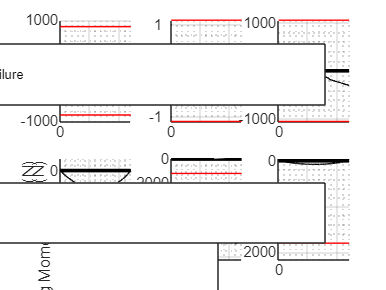


subplot(1, 2, 1)
hold on; grid on; grid minor;
plot(x, SFD_envelope, 'r', 'DisplayName', 'SFD envelope')
plot([0, L], [0, 0], 'k', 'LineWidth', 2, 'HandleVisibility', 'off'); 
legend('Location', 'southeast');
xlabel('Distance along bridge (mm)');
ylabel('Shear Force (N)');